## TEOS10: GSW Toolbox

load TEOS10_datav7.mat
whos

  Name      Size            Bytes  Class     Attributes

  CT        7x1                56  double              
  SA        7x1                56  double              
  SP        7x1                56  double              
  lat       1x1                 8  double              
  long      1x1                 8  double              
  p         7x1                56  double              
  t         7x1                56  double              



Compute Absolute Salinity and Conservative Temperature from in situ temperature, practical salinity, pressure, and position

SA = gsw_SA_from_SP(SP,p,long,lat)

SA =    34.7392
   34.4650
   34.7736
   34.8435
   34.8637
   34.8740
   34.8777


CT = gsw_CT_from_t(SA,t,p)

CT =    19.5130
    3.5588
    1.8157
    1.3434
    1.1583
    1.0518
    1.0073


### Compare in situ temperature with CT

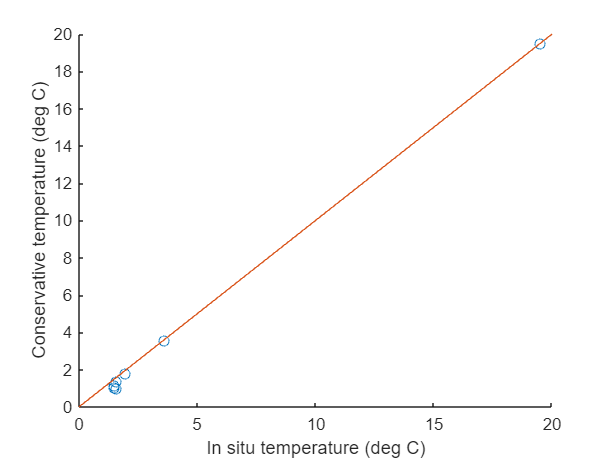

figure
scatter(t,CT)
hold on
plot([0 20],[0,20]) % adds the 1:1 line
xlabel('In situ temperature (deg C)')
ylabel('Conservative temperature (deg C)')

### Calculate density and plot the profile

Compute depth from pressure and then density (**note, depth is negative**)

% first compute depth from pressure
z = gsw_z_from_p(p,lat) 

z = 1.0e+03 *

         0
   -1.0004
   -2.0010
   -3.0019
   -4.0020
   -5.0026
   -6.0026


rho = gsw_rho(SA,CT,p)

rho = 1.0e+03 *

    1.0246
    1.0319
    1.0370
    1.0417
    1.0462
    1.0506
    1.0549


Plot the vertical density profile

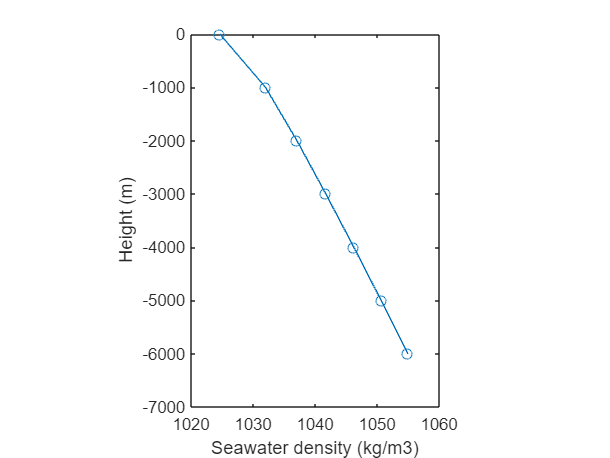

figure
plot(rho,z,'o-')
xlabel('Seawater density (kg/m3)')
ylabel('Height (m)')
pbaspect([1 1.5 1]) % this command changes the PlotBox aspect ratio

### Compute potential density anomaly (sigma) at 2000 dbar

p_ref = 2000;
pot_rho_2 = gsw_rho(SA,CT,p_ref);
sigma_2 = pot_rho_2 - 1000

sigma_2 =    33.0430
   36.4037
   36.8904
   37.0064
   37.0456
   37.0670
   37.0754


pot_rho_0 = gsw_rho(SA,CT,0);
sigma_0 = pot_rho_0 - 1000

sigma_0 =    24.5709
   27.2768
   27.6744
   27.7651
   27.7942
   27.8097
   27.8156


There are convenience commands for these calculations

% sigma_0 = gsw_sigma0(SA,CT);
% sigma_2 = gsw_sigma2(SA,CT);

Now we plot the profiles. In this example you will also learn how to use subplots

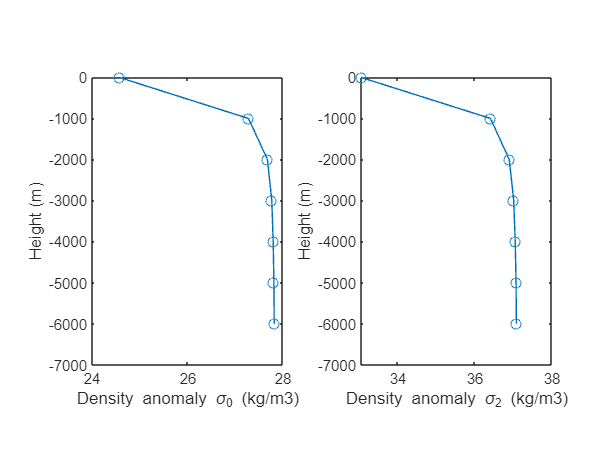

figure
subplot(1,2,1) % (no of rows,no of columns,panel)
plot(sigma_0,z,'o-')
xlabel('Density anomaly \sigma_0 (kg/m3)')
ylabel('Height (m)')
pbaspect([1 1.5 1])
subplot(1,2,2)
plot(sigma_2,z,'o-')
xlabel('Density anomaly \sigma_2 (kg/m3)')
ylabel('Height (m)')
pbaspect([1 1.5 1])

Check the ranges! They will be used in the next diagrams.

### Plot a SA-CT diagram at p_ref=2000 dbar 

We will use the ranges from the previous plot

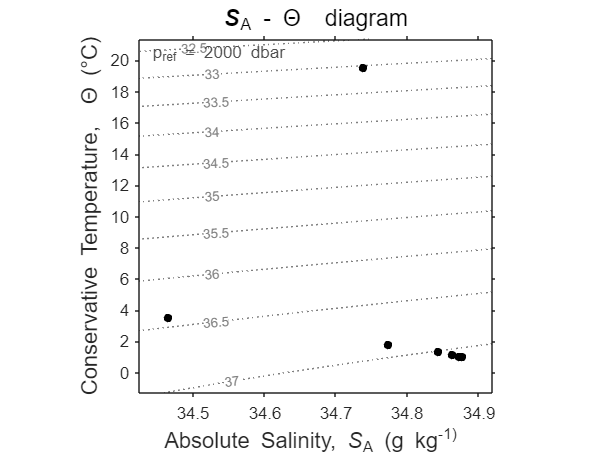

figure
% the 4th array is the range of the X-axis 
% (note the strange syntax in labels)
gsw_SA_CT_plot(SA,CT,p_ref,32.5:0.5:38,'\itS\rm_A - \Theta  diagram'); 

Fit the points to a polynomial for "nice" plotting. A *spline* is an optimal polynomial fitting of the points using an interpolating axis

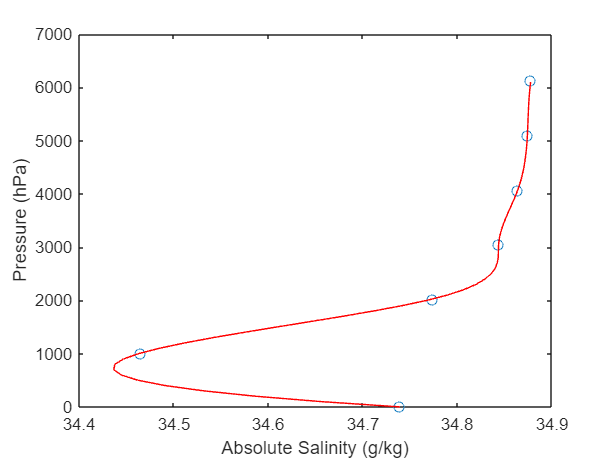

p_i = min(p):100:max(p); % create a pressure axis with many points (every 100 dbar) 
SA_i = spline(p,SA,p_i); 
CT_i = spline(p,CT,p_i);
figure
plot(SA,p,'o')
hold on 
plot(SA_i,p_i,'r-')
xlabel('Absolute Salinity (g/kg)')
ylabel('Pressure (dbar)')

### Replot the previous diagram at 2000 dbar and add the spline

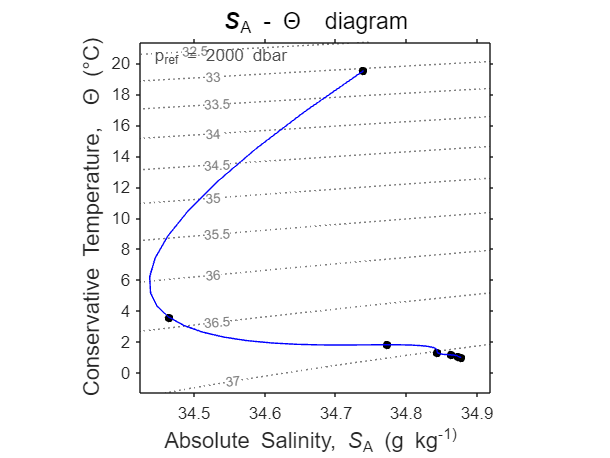

figure
gsw_SA_CT_plot(SA,CT,p_ref,32.5:0.5:38,'\itS\rm_A - \Theta  diagram');
hold on
plot(SA_i,CT_i,'b-')

### Diagram at 0 dbar

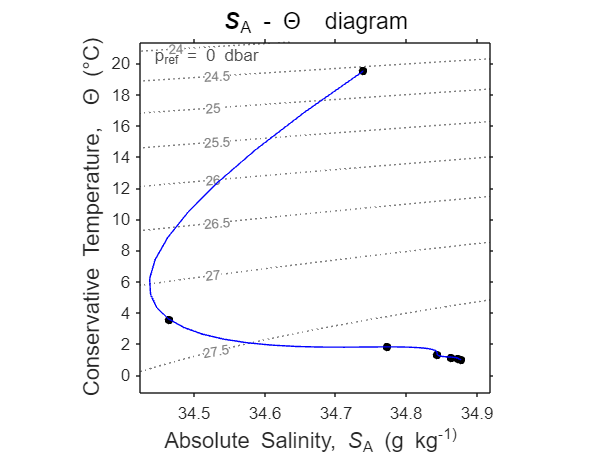

figure
gsw_SA_CT_plot(SA,CT,0,24:0.5:28,'\itS\rm_A - \Theta  diagram');
hold on
plot(SA_i,CT_i,'b-')